# EXAMPLE 2: MULTIPLE WIND HISTORIES

The vertical bridge response is now computed for different values of the mean wind velocity and compared to displacements from a time-domain simulation.

## Bridge modelling

#### Bridge modal properties

phi and wn are the mode shapes and eigen frequencies of the main span, respectively.

clearvars;close all;clc;
load('bridgeModalProperties.mat','wn','phi')
phiV = squeeze(phi(2,:,:)); % Vertical mode shapes:
wnV = squeeze(wn(2,:)); % Vertical mode shapes:
[Nmodes,Nyy]=size(phiV); % Nyy: number of "nodes"
% Structural modal damping ratio for the  Bridge deck: it is here taken as 0.5 % for every mode
Bridge.zetaStruct = 5e-3.*ones(1,Nmodes);

#### Bridge structural properties

The mechanical properties of the single-span suspension bridge are considered.

Bridge.B = 12.3 ; % width of the bridge deck (m)
Bridge.D = 2.76 ; % height of the bridge deck (m)
Bridge.L = 446 ; % Length of the main span (m)
Bridge.x = linspace(0,1,Nyy) ; % normalized bridge main span
Bridge.m = 5350 ; % lineic mass of girder (kg/m)
Bridge.mc = 408 ; % lineic mass of cable (kg/m)
Bridge.m_theta = 82430; % torsional stifness (kg.m^2/m)
Bridge.k = 1/4; % bridge constant . cf aerodynamic of streamlined bridge
% aerodynamic coefficient (quasi steady terms)
Bridge.Cd = 1;% drag coefficient
Bridge.dCd = 0;% first derivative of drag coefficient
Bridge.Cl = 0.1;% lift coefficient
Bridge.dCl = 3;% first derivative of lift coefficient
Bridge.Cm = 0.02;% pitching moment coefficient
Bridge.dCm = 1.12;% first derivative of pitching moment coefficient


#### Selection of position where the response is computed

The response is here computed at 1/3 of the bridge. Note that x is the normalized span length ranging from  0 to 1

[~,position] = min(abs(Bridge.x-1/3));

## simulation of the bridge response for multiples wind histories.

% STD of vertical bridge displacement in frequency domain (FD)

Bridge.DOF = 'vertical';
Bridge.wn = wnV; 
Bridge.phi = phiV; 

#### Definition of the frequency vector

tmax = 600; % relatively short duration used to speed-up the computation
fs = 5; % sampling frequency of 5Hz is chosen
Nfreq = 500; % number of frequency steps is arbitrary
f = logspace(log10(1/tmax),log10(fs/2),Nfreq);

#### Turbulence characteristics and computation of the buffeting response

Niter = 30; % number of case considered in the frequency domain
meanU = linspace(2,30,Niter); % mean wind speed computed
clear Wind
Wind.Cuy = 8; % decay coefficient for co-coherence for u-component along bridge span
Wind.Cwy = 8; % decay coefficient for co-coherence for w-component along bridge span
Wind.f = f;

% Integral length scales
Lu = 150;
Lw = 50;

Srz = zeros(Nyy,Nfreq); % PSD of the vertical displacement response for all the iterations
Doz_FD = zeros(1,Niter); % STD of the vertical displacement response for all the iterations

tic
for ii=1:Niter,
    Wind.U = meanU(ii);
    stdU = 0.2*Wind.U;
    stdW = 0.6*stdU;
    [Su] = VonKarmanSpectrum(f,Wind.U,stdU,Lu,'u');
    [Sw] = VonKarmanSpectrum(f,Wind.U,stdW,Lw,'w');
    % Storage of the data into the structure variableWind .
    Wind.Su = Su;
    Wind.Sw = Sw;
    [Srz(ii,:)] = dynaRespFD3(Bridge,Wind,position);
    Doz_FD(ii) = sqrt(trapz(f,Srz(ii,:)));
end
toc

Elapsed time is 9.093853 seconds.


## Comparison with a time-domain approach

For the sake of brevity, the response data obtained in the time-domain where precomputed and are here simply loaded

load('DynamicDispl.mat')

#### Comparison in terms of the standard deviation of the vertical displacement response

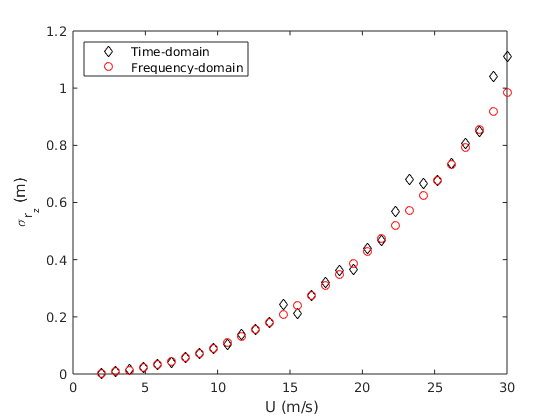

figure
hold on;box on;
plot(Uref,std(Doz,0,2)./0.2,'kd')
plot(meanU,Doz_FD./0.2,'ro')
legend('Time-domain','Frequency-domain','location','NorthWest');
xlabel(' U (m/s)');
ylabel('\sigma_{r_{z}} (m)');

#### Comparison in terms of PSD of the vertical displacement response

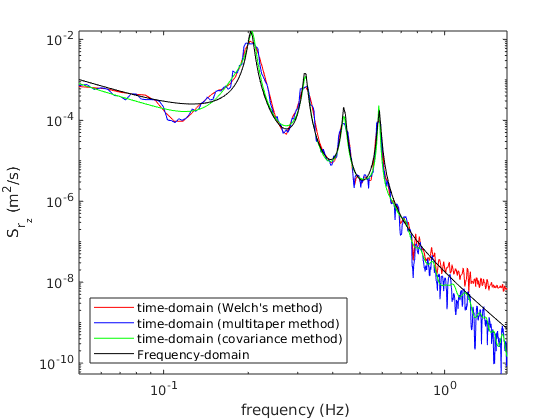

ni = 10; % choice of iteration 
fsTD = 1/median(diff(t));
[S1,freq1]=pwelch(Doz(ni,:),[],[],[],fsTD);
[S2,freq2]=pmtm(Doz(ni,:),4,numel(t),fsTD);
[S3,freq3]=pcov(Doz(ni,:),50,numel(t),fsTD);
figure
axis tight
hold on;box on
plot(freq1,S1,'r',freq2,S2,'b',freq3,S3,'g');
axis tight
xlim([0.05,fs/3])
plot(f,Srz(ni,:),'k');
set(gca,'Xscale','log')
set(gca,'Yscale','log')
xlabel(' frequency (Hz)');
ylabel('S_{r_z} (m^2/s)');
legend('time-domain (Welch''s method)','time-domain (multitaper method)',...
    'time-domain (covariance method)',...
    'Frequency-domain','location','SouthWest')